# **Regression Modeling using MATLAB**

This MATLAB Live Script is designed for the MA6600 Artificial Intelligence and Machine Learning Module for the UG Mathematics degree programm at Kingston University.

Copyright @ *Nabajeet Barman (nabajeetbarman4@gmail.com)*

Regression model is a machine learning model that outputs a continuous numeric response. Eg: Predicting stock prices is a regression problem.

                                                     [Source](https://www.mathworks.com/help/stats/regression-learner-app.html)

## Types of Regression Models

- Linear Regression

- Decision Trees

- Support Vector Machines

- Gaussian Process Regression

## Evaluating Regression Models

- Mean Absolute Error (MAE): The average magnitude of the residuals

- Mean Square Error (MSE): The average of the squared residuals

- Root MSE (RMSE): The square root of MSE

- R-squared

MAE, MSE and RMSE are measures of error and are useful for comparing between models.

R-Squared is a measure of goodness of fit vs. a flat line model. The values range between 0 and 1.

## Evaluating your model in MATLAB

Use metrics such as MAE, RMSE and R-squared to evaluate and compare the different regression models.

Use different visualization charts to get an understanding of how your model is performing.

Look for overall biases and areas where the model is performing poorly. One should consider the model's application focus when evaluating its performance.

# The Boston House Price Dataset

The Boston House Price Dataset involves the prediction of a house price in thousands of dollars given details of the house and its neighborhood. It is a regression problem. There are 506 observations with 13 input variables and 1 output variable. The variable names are as follows:

- *CRIM (Crime Rate):* per capita crime rate by town.

- *ZN (Size of Residential Land)*: proportion of residential land zoned for lots over 25,000 sq.ft.

- *INDUS (Industrial Factor)*: proportion of nonretail business acres per town.

- *CHAS: Charles River dummy variable* (= 1 if tract bounds river; 0 otherwise).   %% should be deleted as not useful!!!!

- *NOX (Nitrogen Oxide Concentration)*: nitric oxides concentration (parts per 10 million).

- *RM (Average number of Rooms)*: average number of rooms per dwelling.

- *AGE (House Age)*: Number of house built prior to 1940.

- *DIS (Employment Center)*: weighted distances to five Boston employment centers.

- *RAD (Convenience)*: index of accessibility to radial highways.

- *TAX (Property Tax)*: full-value property-tax rate per $10,000.

- *PTRATIO*: pupil-teacher ratio by town.

- *B:* 1000(Bk – 0.63)^2 where Bk is the proportion of blacks by town.

- *LSTAT (Status of Population)*: % lower status of the population.

- ***MEDV*****: Median value of owner-occupied homes in $1000s. **

`Note:` The baseline performance of predicting the mean value is an `RMSE` of approximately `9.21 thousand dollars`.

## Downloading the Dataset 

% code from https://www.mathworks.com/products/demos/machine-learning/boosted-regression.html
filename = 'housing.txt';
urlwrite('http://archive.ics.uci.edu/ml/machine-learning-databases/housing/housing.data',filename);
inputNames = {'CRIM','ZN','INDUS','CHAS','NOX','RM','AGE','DIS','RAD','TAX','PTRATIO','B','LSTAT'};
outputNames = {'MEDV'};
housingAttributes = [inputNames,outputNames];

Importing into the workspace in a proper format (as was done with the titanic dataset)

format_spec = '%8f%7f%8f%3f%8f%8f%7f%8f%4f%7f%7f%7f%7f%f%[^\n\r]';
file_id = fopen(filename,'r');
data_array = textscan(file_id, format_spec, 'Delimiter', '', 'WhiteSpace', '',  'ReturnOnError', false);
fclose(file_id);
housing = table(data_array{1:end-1}, 'VariableNames', {'CRIM','ZN','INDUS','CHAS','NOX','RM','AGE','DIS','RAD','TAX','PTRATIO','B','LSTAT', 'MEDV'});

% Delete the file and clear temporary variables
clearvars filename format_spec file_id data_array ans;
delete housing.txt

% define input variables (predictors) and output (target) variables -- for
% easier usage
X = housing{:,inputNames};
Y = housing{:,outputNames};

## Model 01: Linear Regression

A linear regression model is an equation where each feature (predictor) is multiplied by a coefficient and summed together to predict the response. An additive constant, or intercept term is also included. 

mdl = fitlm(housing,'ResponseVar','MEDV')

mdl = Linear regression model:
    MEDV ~ 1 + CRIM + ZN + INDUS + CHAS + NOX + RM + AGE + DIS + RAD + TAX + PTRATIO + B + LSTAT

Estimated Coefficients:
                    Estimate        SE         tStat        pValue  
                   __________    _________    ________    __________

    (Intercept)        36.459       5.1035      7.1441    3.2834e-12
    CRIM             -0.10801     0.032865     -3.2865     0.0010868
    ZN                0.04642     0.013727      3.3816    0.00077811
    INDUS            0.020559     0.061496     0.33431       0.73829
    CHAS               2.6867      0.86158      3.1184      0.001925
    NOX               -17.767       3.8197     -4.6513    4.2456e-06
    RM                 3.8099      0.41

### **Choose a Fitting Method**

There are three ways to fit a model to data:

- [Least-Squares Fit](https://www.mathworks.com/help/stats/linear-regression-model-workflow.html#btcpwno)

- [Robust Fit](https://www.mathworks.com/help/stats/linear-regression-model-workflow.html#btcpwmd)

- [Stepwise Fit](https://www.mathworks.com/help/stats/linear-regression-model-workflow.html#btcpwm_)

**Least-Squares Fit**

Use [`fitlm`](https://www.mathworks.com/help/stats/fitlm.html) to construct a least-squares fit of a model to the data. This method is best when you are reasonably certain of the model’s form, and mainly need to find its parameters. This method is also useful when you want to explore a few models. The method requires you to examine the data manually to discard outliers, though there are techniques to help (see [Examine Quality and Adjust Fitted Model](https://www.mathworks.com/help/stats/linear-regression-model-workflow.html#btb50q6)).

**Robust Fit**

Use [`fitlm`](https://www.mathworks.com/help/stats/fitlm.html) with the `RobustOpts` name-value pair to create a model that is little affected by outliers. Robust fitting saves you the trouble of manually discarding outliers. However, [`step`](https://www.mathworks.com/help/stats/linearmodel.step.html) does not work with robust fitting. This means that when you use robust fitting, you cannot search stepwise for a good model.

**Stepwise Fit**

Use [`stepwiselm`](https://www.mathworks.com/help/stats/stepwiselm.html) to find a model, and fit parameters to the model. [`stepwiselm`](https://www.mathworks.com/help/stats/stepwiselm.html) starts from one model, such as a constant, and adds or subtracts terms one at a time, choosing an optimal term each time in a greedy fashion, until it cannot improve further. Use stepwise fitting to find a good model, which is one that has only relevant terms. The result depends on the starting model. Usually, starting with a constant model leads to a small model. Starting with more terms can lead to a more complex model, but one that has lower mean squared error. See [Compare large and small stepwise models](https://www.mathworks.com/help/stats/stepwise-regression.html#bs9ss9b).

You cannot use robust options along with stepwise fitting.

% alternatively, using RobustOpts option!!!
mdl = fitlm(X,Y,'linear', 'RobustOpts','on')

mdl = Linear regression model (robust fit):
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9 + x10 + x11 + x12 + x13

Estimated Coefficients:
                   Estimate        SE         tStat        pValue  
                   _________    _________    ________    __________

    (Intercept)       7.1782        4.099      1.7512      0.080537
    x1              -0.12595     0.026397     -4.7715     2.414e-06
    x2              0.027216     0.011026      2.4684       0.01391
    x3             -0.014011     0.049392    -0.28366       0.77679
    x4                1.2367      0.69201      1.7872      0.074525
    x5               -6.2581        3.068     -2.0398      0.041902
    x6                6.2406      0.33567      18.59

% 'y ~ x1 + x2 + x3' is a three-variable linear model with intercept.
% 'y ~ x1 + x2 + x3 - 1' is a three-variable linear model without intercept.

### **Examine Quality and Adjust Fitted Model**

tbl = anova(mdl)

tbl = 14×5 table
             SumSq     DF     MeanSq       F          pValue  
             ______    ___    ______    ________    __________

    x1       330.73      1    330.73      22.767     2.414e-06
    x2       88.511      1    88.511      6.0931       0.01391
    x3       1.1688      1    1.1688    0.080462       0.77679
    x4       46.397      1    46.397       3.194      0.074525
    x5       60.442      1    60.442      4.1609      0.041902
    x6       5020.9      1    5020.9      345.64    7.9119e-59
    x7       225.13      1    225.13      15.498    9.4516e-05
    x8       528.91      1    528.91       36.41    3.1478e-09
    x9       122.38      1   

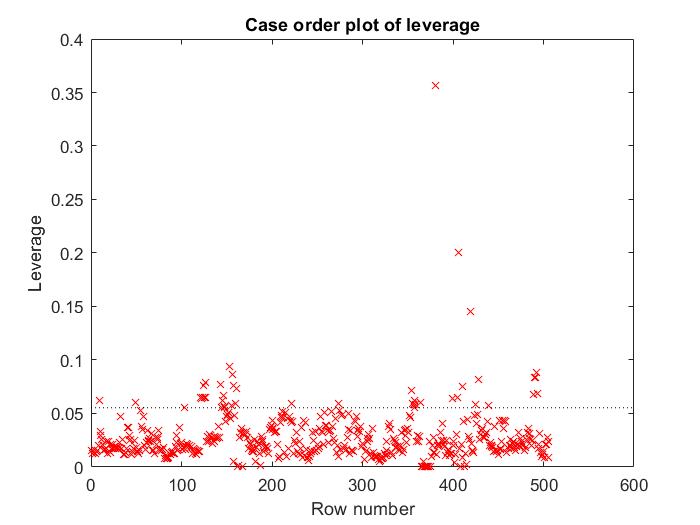

% Diagnostic plots help you identify outliers, and see other problems in your model or fit. 
plotDiagnostics(mdl)

An effect **leverage plot**, also known as added variable **plot** or partial regression **leverage plot**, shows the unique effect of a term in the model. A horizontal line shows the constrained model without the term; a slanted line shows the unconstrained model with the term. The points with high extreme values of X are said to have high leverage. High leverage points have a greater ability to move the fitted line. If these points fall outside the overall pattern, they can be influential. 

There are a few points with high leverage. But this plot does not reveal whether the high-leverage points are outliers.

**What to do in case if a point is very influential?**

First, make sure that the observation is correctly recorded - that the data is as intended. Also check, if the conclusions change in case of exclusion/inclusion of the high leverage point(s). Can we get more observations near that value of X?

#### **Plot with Cook's distance**

In statistics, **Cook's distance** (often referred to as **Cook's D**) is a common measurement of a data point's influence. It's a way to find influential outliers in a set of predictor variables when performing a least-squares regression analysis. The concept was introduced by an American statistician named R.

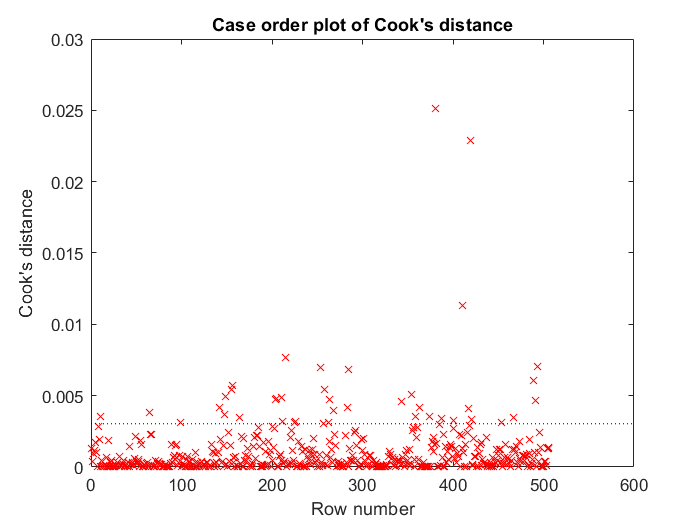

plotDiagnostics(mdl,'cookd')

#### **Residuals — Model Quality for Training Data**

There are several residual plots to help you discover errors, outliers, or correlations in the model or data. The simplest residual plots are the default histogram plot, which shows the range of the residuals and their frequencies, and the probability plot, which shows how the distribution of the residuals compares to a normal distribution with matched variance.

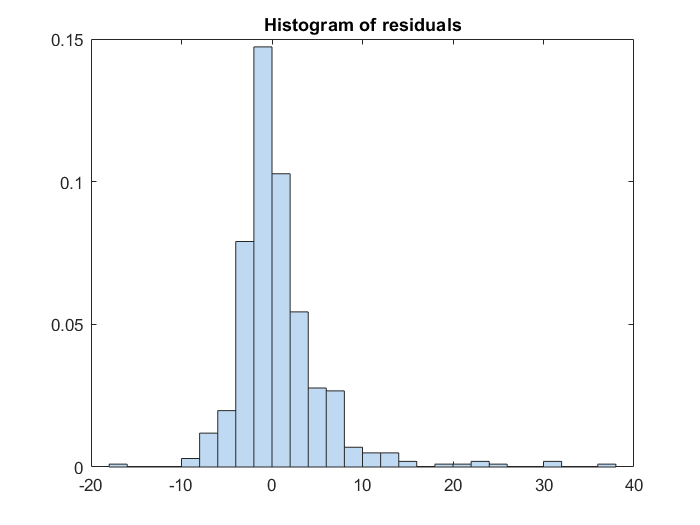

plotResiduals(mdl)

The observations above 28 and below -10 are potential outliers!!!!

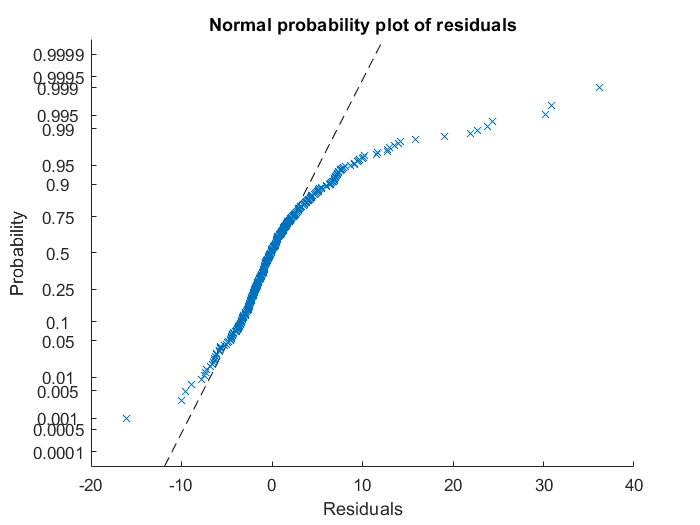

plotResiduals(mdl,'probability')

The potential outliers appear on this plot as well (bottom left most and top right ones). 

Otherwise, the probability plot seems reasonably straight, meaning a reasonable fit to normally distributed residuals.

## Model 02: Regression Tree

Regression trees pass observations through a sequence of binary conditions on the predictor values called ‘nodes’. A particular sequence of nodes is called a ‘branch’. The nodes at the tip of each branch are called ‘leaves’, where a fixed response value is predicted for all observations that reach this leaf. 

Create nodes by finding a binary condition on a predictor that best splits the training observations that reach the node into two groups. The ‘best’ split is determined by calculating the sum of squared residuals for both groups. The group mean is used as the 'predicted’ value. Nodes are considered leaves when they can’t be split further. 

Trees are very flexible and do not require:

- Polynomial features to capture nonlinear predictor-response relationships

- Additional features for categorical predictors

- Standardization of predictor values

Trees may not capture interactions between predictors, though additional options can be specified to capture these terms.

% Using Cross Validation
rng(10); % For reproducibility - changing this will change the result. 
% SAME is true for the app - each time you redo the steps, it will produce results with different RMSE values
% Set aside 90% of the data for training
model = fitrtree(X,Y); % model is a RegressionTree model. % fitctree for classification trees
% Cross-validate the regression tree using 10-fold cross-validation.
cvmodel = crossval(model);
%cvmodel = crossval(model,'KFold',5); % default is 10
L = kfoldLoss(cvmodel); % 10-fold cross-validated mean-squared error.
fprintf('Root Mean-square testing error = %f\n',sqrt(L));

Root Mean-square testing error = 4.159023


% Using percent holdout
rng(10); % For reproducibility
% Set aside 90% of the data for training
cv = cvpartition(height(housing),'holdout',0.1);
mdl = fitrtree(X(cv.training,:),Y(cv.training,:),'MinLeafSize', 4, 'Surrogate', 'off');
L = loss(mdl,X(cv.test,:),Y(cv.test));
fprintf('Root Mean-square testing error = %f\n',sqrt(L));

Root Mean-square testing error = 3.458227


### Plot Fit Against Test Data

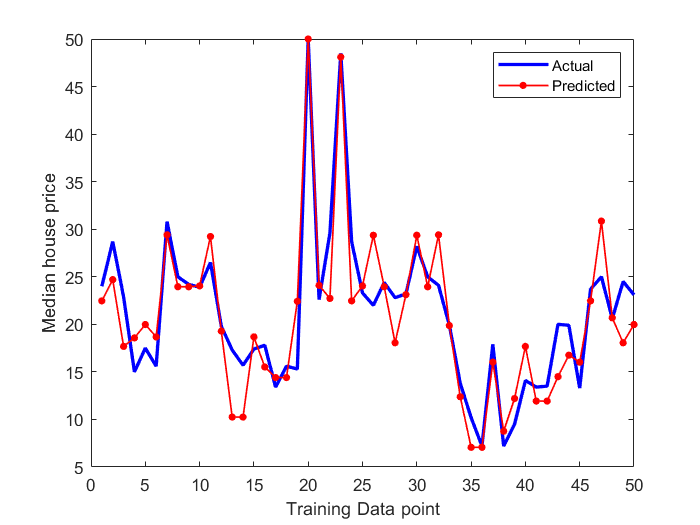

%figure(1);
plot(Y(cv.test),'b','LineWidth',2), 
hold on
plot(predict(mdl,X(cv.test,:)),'r.-','LineWidth',1,'MarkerSize',15)
% Observe first hundred points, pan to view more
%xlim([0 100])
legend({'Actual','Predicted'})
xlabel('Training Data point');
ylabel('Median house price');
hold off

% similarly you can do for the training dataset

### Plotting the predictor importance

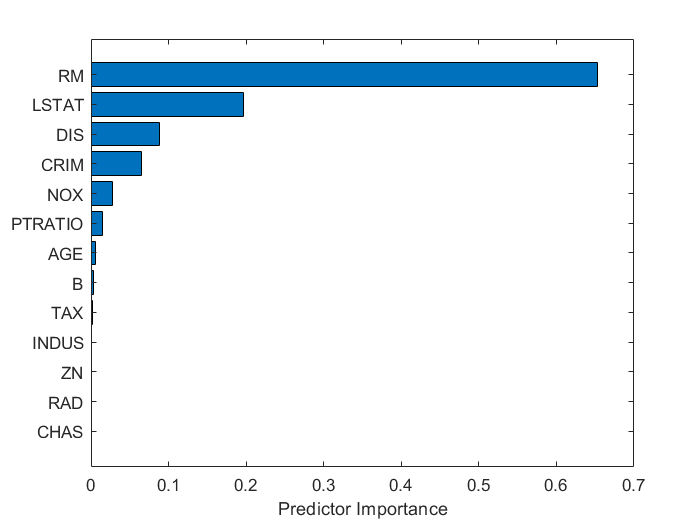

% Plot the predictors sorted on importance
[predictorImportance,sortedIndex] = sort(mdl.predictorImportance);
figure(2);
barh(predictorImportance)
set(gca,'ytickLabel',inputNames(sortedIndex))
xlabel('Predictor Importance')

A good idea would be remove the very low important features and retrain your model (reducing both training and testing complexity).

## Model 03: Neural Network

Data Preparation (generate the training set and data set)

% Cross varidation (train: 70%, test: 30%)
cv = cvpartition(size(housing,1),'HoldOut',0.3);
idx = cv.test;
% Separate to training and test data
dataTrain = housing(~idx,:);
dataTest  = housing(idx,:);
% training predictors and target 
pred_train = dataTrain{:,inputNames}';
target_train = dataTrain{:,outputNames}';
% test predictors and target 
pred_test = dataTest{:,inputNames}';
target_test = dataTest{:,outputNames}';

%%Neural Networks
% Create and train feedforward neural network
net = feedforwardnet(10, 'trainlm');% create a network
%net.trainParam.epochs = 1000;% set training times
%net.trainParam.goal = 0.0000001;% setting convergence error
[net, tr] = train (net, pred_train, target_train);% training network
% network simulation, test data
predict_test = sim(net, pred_test);% put into the network to output data

Assessing the performance of the trained network

% The default performance function is mean squared error.
perf = perform(net,pred_test,target_test)

perf = 2.2961e+04

Result analysis

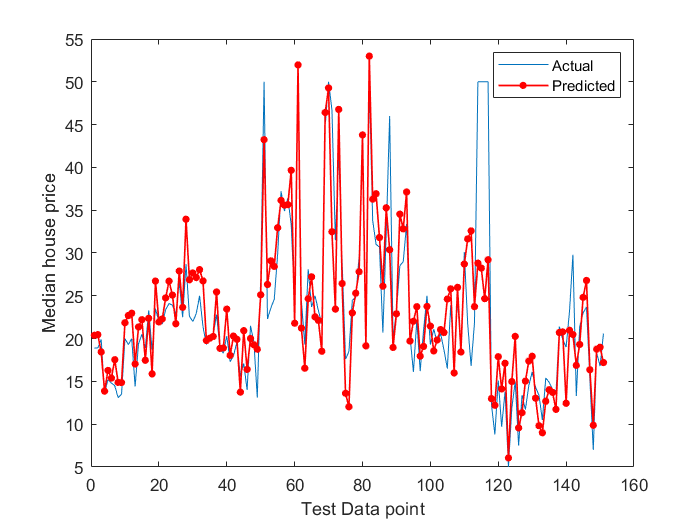

target_test = target_test';
err_prices = target_test-predict_test;% error
[mean(err_prices) std(err_prices)];% average, standard deviation
figure(1);
plot(target_test);
hold on;
plot(predict_test,'r.-','LineWidth',1,'MarkerSize',15);
%xlim([1 length(t_test)]);
hold off;
legend({'Actual','Predicted'})
xlabel('Test Data point');
ylabel('Median house price');